# Linear Regression With Error Estimate

Fit a linear model to a set of data points and plot the results, including an estimate of a 95% prediction interval.

Create a few vectors of sample data points *(x,y)*. Use `polyfit` to fit a first degree polynomial to the data. Specify two outputs to return the coefficients for the linear fit as well as the error estimation structure. 

x = 1:100; 
y = -0.3*x + 2*randn(1,100); 
[p,S] = polyfit(x,y,1); 

Evaluate the first-degree polynomial fit in `p` at the points in `x`. Specify the error estimation structure as the third input so that `polyval` calculates an estimate of the standard error. The standard error estimate is returned in `delta`.

[y_fit,delta] = polyval(p,x,S);

Plot the original data, linear fit, and 95% prediction interval $y\pm 2\Delta$.

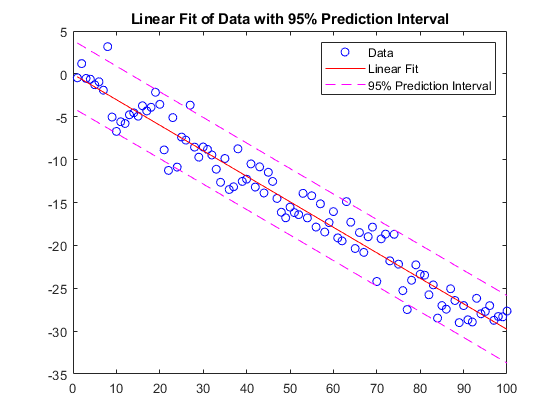

plot(x,y,'bo')
hold on
plot(x,y_fit,'r-')
plot(x,y_fit+2*delta,'m--',x,y_fit-2*delta,'m--')
title('Linear Fit of Data with 95% Prediction Interval')
legend('Data','Linear Fit','95% Prediction Interval')

*Copyright 2018 The MathWorks, Inc.*